# Calibration of CAPRICEP procedure

Licence 

Copyright 2020 Hideki Kawahara

 Licensed under the Apache License, Version 2.0 (the "License"); you may not use this file except in compliance with the License. You may obtain a copy of the License at

  http://www.apache.org/licenses/LICENSE-2.0

Unless required by applicable law or agreed to in writing, software distributed under the License is distributed on an "AS IS" BASIS, WITHOUT WARRANTIES OR CONDITIONS OF ANY KIND, either express or implied. See the License for the specific language governing permissions and limitations under the License.

close all
clear variables

## Initialize environment

fs = 44100;

## SNR test with a constant gain

test target functions

analysisStr = capricepResponseTest(fs, tResponse, nRepetition, outChannel, inChannel, varargin)

specStr = capricepResponseAnalysis(analysisStr)

reportStr = capricepResponseReport(specStr)

tResponse = 100;
nRepetition = 30;
outChannel = 'L-ch';
inChannel = 1;
option = struct;
option.gain = 'flat';
option.snr = 30;
option.fs = fs;
option.testMode = 'SNR';
option.calibrationConst = 0;
analysisStr = capricepResponseTest(fs, tResponse, nRepetition, outChannel, inChannel, 'simulator', option)

analysisStr = フィールドをもつ struct :
          simulationOut: [1×1 struct]
                     fs: 44100
                tspName: "setCAPRICEP100msRc.mat"
              tResponse: 100
            nRepetition: 30
       calibrationConst: 0
                   fLow: 40
                pinkLPC: [1×51 double]
              xTestPink: [197837×1 double]
             outChannel: 'L-ch'
            numChannels: 1
     testSignalDuration: 4.4861
              yRecorded: [241937×1 double]
             yRecovered: [241937×1 double]
       orthogonalSignal: [241937×4 double]
    orthogonalSignalRef: [241937×4 double]
            elapsedTime: 0.2708
                   lAeq: -30.6917
     elapsedTimeRecover: 0.1830


specStr = capricepResponseAnalysis(analysisStr)

specStr = フィールドをもつ struct :
                  shortSpec: [65536×1 double]
                   longSpec: [65536×1 double]
         deviationPowerSpec: [65536×1 double]
            randomPowerSpec: [65536×1 double]
              frequencyAxis: [1×65536 double]
               prePowerSpec: [65536×1 double]
                         fs: 44100
                    tspName: "setCAPRICEP100msRc.mat"
                  tResponse: 100
                nRepetition: 30
                    pinkLPC: [1×51 double]
                 outChannel: 'L-ch'
                numChannels: 1
    initialAnalysisPosition: 107738
           rawShortResponse: [4410×4 double]
       averageShortResponse: [4410×1 double]
              timeAxisShort: [4410×1 double]
               timeAxisLong: [17640×1 double]
           headMarginSample: 441
        averageLongResponse: [17640×1 double]
           orthogonalSignal: [241937×4 double]
                  sumSignal: [241937×1 double]
                       lAeq: -30.6917
    

%reportStr = capricepResponseReport(specStr);
%reportStr

%figure;plot(specStr.averageShortResponse);grid on

### SNR linearity check

This took 250s.

tResponse = 100;
nRepetition = 30;
outChannel = 'L-ch';
inChannel = 1;
option = struct;
option.calibrationConst = 0;
option.gain = 'flat';
option.snr = 30;
option.fs = fs;
option.testMode = 'SNR';
nIteration = 100;
snrList = 10:10:60;
snrTestResult = zeros(nIteration, length(snrList));
tic
for ii = 1:nIteration
    for jj = 1:length(snrList)
        option.snr = snrList(jj);
        analysisStr = capricepResponseTest(fs, tResponse, nRepetition, outChannel, inChannel, 'simulator', option);
        specStr = capricepResponseAnalysis(analysisStr);
        snrTestResult(ii, jj) = 10*log10(sum(abs(specStr.shortSpec) .^2)) ...
            - 10*log10(sum(specStr.randomPowerSpec));
    end
    if rem(ii, 10) == 0
        toc
    end
end

経過時間は 23.861454 秒です。
経過時間は 47.599062 秒です。
経過時間は 77.978332 秒です。
経過時間は 102.857863 秒です。
経過時間は 127.427296 秒です。
経過時間は 151.312356 秒です。
経過時間は 174.680348 秒です。
経過時間は 198.097383 秒です。
経過時間は 222.190946 秒です。
経過時間は 245.474122 秒です。


toc

経過時間は 245.476847 秒です。


#### display the results

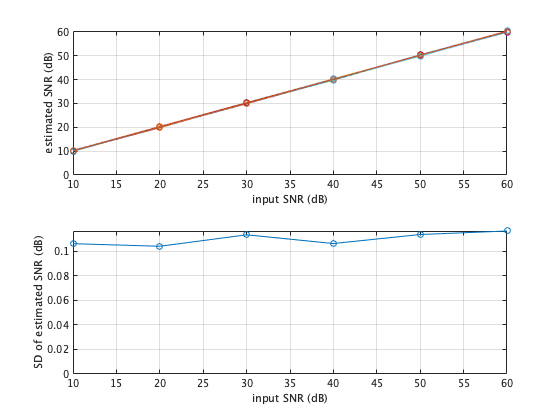

figure;
subplot(211)
plot(snrList, snrTestResult,'o-');grid on;
xlabel('input SNR (dB)')
ylabel('estimated SNR (dB)')
subplot(212)
plot(snrList, std(snrTestResult),'o-'); grid on;
axis([snrList(1) snrList(end) 0 max(std(snrTestResult))])
xlabel('input SNR (dB)')
ylabel('SD of estimated SNR (dB)')

## Actual acoustic system measurement

analysisStr = フィールドをもつ struct :
                     fs: 44100
                tspName: "setCAPRICEP400msRc.mat"
              tResponse: 400
            nRepetition: 30
       calibrationConst: 0
                   fLow: 40
                pinkLPC: [1×51 double]
              xTestPink: [791345×1 double]
             outChannel: 'L-ch'
            numChannels: 1
     testSignalDuration: 17.9443
              yRecorded: [880640×1 double]
             yRecovered: [880640×1 double]
       orthogonalSignal: [880640×4 double]
    orthogonalSignalRef: [880640×4 double]
            elapsedTime: 21.8401
                   lAeq: -42.6676
     elapsedTimeRecover: 1.1130


specStr = フィールドをもつ struct :
                  shortSpec: [262144×1 double]
                   longSpec: [262144×1 double]
         deviationPowerSpec: [262144×1 double]
            randomPowerSpec: [262144×1 double]
              frequencyAxis: [1×262144 double]
               prePowerSpec: [262144×1 double]
                         fs: 44100
                    tspName: "setCAPRICEP400msRc.mat"
                  tResponse: 400
                nRepetition: 30
                    pinkLPC: [1×51 double]
                 outChannel: 'L-ch'
                numChannels: 1
    initialAnalysisPosition: 301999
           rawShortResponse: [17640×4 double]
       averageShortResponse: [17640×1 double]
              timeAxisShort: [17640×1 double]
               timeAxisLong: [70560×1 double]
           headMarginSample: 441
        averageLongResponse: [70560×1 double]
           orthogonalSignal: [880640×4 double]
                  sumSignal: [880640×1 double]
                       lAeq: -42.

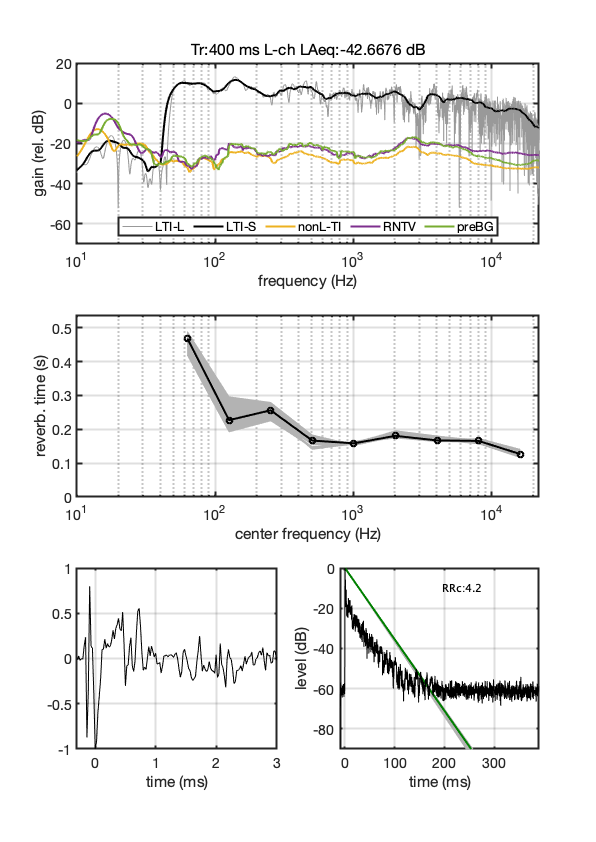

reportStr = フィールドをもつ struct :
               specStr: [1×1 struct]
    figureHandleReport: [1×1 Figure]


acoustOn = 1;
if acoustOn == 1
tResponse = 400;
nRepetition = 30;
outChannel = 'L-ch';
inChannel = 1;

analysisStr = capricepResponseTest(fs, tResponse, nRepetition, outChannel, inChannel)
specStr = capricepResponseAnalysis(analysisStr)
reportStr = capricepResponseReport(specStr)
end

## Nonlinearity check

tResponse = 100;
nRepetition = 30;
outChannel = 'L-ch';
inChannel = 1;
option = struct;
option.gain = 'flat';
option.snr = 150;
option.fs = fs;
option.testMode = 'nonLinear';
option.level = -20;
option.calibrationConst = 0;
nIteration = 10;
analysisStr = capricepResponseTest(fs, tResponse, nRepetition, outChannel, inChannel, 'simulator', option)

analysisStr = フィールドをもつ struct :
          simulationOut: [1×1 struct]
                     fs: 44100
                tspName: "setCAPRICEP100msRc.mat"
              tResponse: 100
            nRepetition: 30
       calibrationConst: 0
                   fLow: 40
                pinkLPC: [1×51 double]
              xTestPink: [197837×1 double]
             outChannel: 'L-ch'
            numChannels: 1
     testSignalDuration: 4.4861
              yRecorded: [241937×1 double]
             yRecovered: [241937×1 double]
       orthogonalSignal: [241937×4 double]
    orthogonalSignalRef: [241937×4 double]
            elapsedTime: 0.2754
                   lAeq: -49.1906
     elapsedTimeRecover: 0.1736


specStr = capricepResponseAnalysis(analysisStr)

specStr = フィールドをもつ struct :
                  shortSpec: [65536×1 double]
                   longSpec: [65536×1 double]
         deviationPowerSpec: [65536×1 double]
            randomPowerSpec: [65536×1 double]
              frequencyAxis: [1×65536 double]
               prePowerSpec: [65536×1 double]
                         fs: 44100
                    tspName: "setCAPRICEP100msRc.mat"
                  tResponse: 100
                nRepetition: 30
                    pinkLPC: [1×51 double]
                 outChannel: 'L-ch'
                numChannels: 1
    initialAnalysisPosition: 107738
           rawShortResponse: [4410×4 double]
       averageShortResponse: [4410×1 double]
              timeAxisShort: [4410×1 double]
               timeAxisLong: [17640×1 double]
           headMarginSample: 441
        averageLongResponse: [17640×1 double]
           orthogonalSignal: [241937×4 double]
                  sumSignal: [241937×1 double]
                       lAeq: -49.1906
    

%reportStr = capricepResponseReport(specStr)

Test loop: It took 38sec

levelList = -60:10:20;
nonLinTestResult = zeros(nIteration, length(levelList));
nonLinGTvalueResult = zeros(nIteration, length(levelList));
tic
for ii = 1:nIteration
    for jj = 1:length(levelList)
        option.level = levelList(jj);
        analysisStr = capricepResponseTest(fs, tResponse, nRepetition, outChannel, inChannel, 'simulator', option);
        specStr = capricepResponseAnalysis(analysisStr);
        nonLinTestResult(ii, jj) = 10*log10(sum(abs(specStr.shortSpec) .^2)) ...
            - 10*log10(sum(specStr.deviationPowerSpec));
        nonLinGTvalueResult(ii, jj) = analysisStr.simulationOut.nlLeveldB;
    end
    if rem(ii, 10) == 0
        toc
    end
end

経過時間は 36.778011 秒です。


toc

経過時間は 36.781305 秒です。


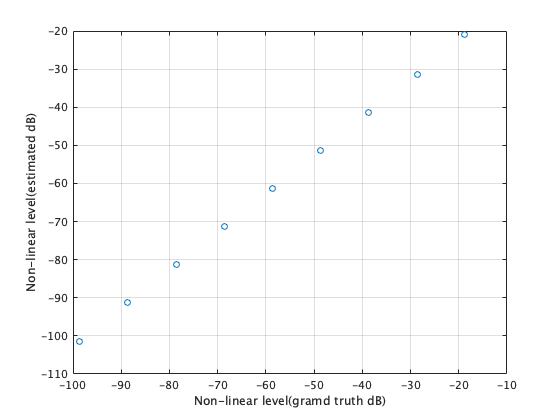

figure;
plot(nonLinGTvalueResult(:), -nonLinTestResult(:), 'o');grid on;
xlabel('Non-linear level(gramd truth dB)')
ylabel('Non-linear level(estimated dB)')